lidar = serialport("COM1", 115200);
map = occupancyMap(15,15,20);
map.GridLocationInWorld = [-7.5 -7.5];
initialPose = [0 0 0];
Angles = {};
Ranges = {};

while true
    if lidar.NumBytesAvailable > 0
        data = read(lidar,2000,"uint8"); 
        
        indicesOfHeader = strfind(data,[170 85]);
        packets = {};
        for i = 1:length(indicesOfHeader)-1
            startIdx = indicesOfHeader(i);
            endIdx = indicesOfHeader(i+1);
            packets{end+1} = data(startIdx:endIdx-1);
        end
        
        %1x40 elements.
        angles = {};
        ranges = {};
        anglesElem = [];
        rangesElem = [];
        for i = 1:numel(packets)
            [anglesElem, rangesElem] = interpreter(packets{i});
            if ~(size(anglesElem,2) < 40)
                angles{end+1} = anglesElem;
                ranges{end+1} = rangesElem;
            end
        end

        %1x400 elements.
%         Angles = {};
%         Ranges = {};
        count = 0;
        elemAngles = zeros(1,400);
        elemRanges = zeros(1,400);
        
        for k = 1:floor(numel(angles)/10)
            idx = 0;
            for i = 1+count:10+count
                currentAngles = angles{i};
                currentRanges = ranges{i};
                for j = 1:40
                    idx = idx + 1;
                    elemAngles(idx) = currentAngles(j);
                    elemRanges(idx) = currentRanges(j);
                end
            end
            count = count + 10;
            Angles{end+1} = elemAngles;
            Ranges{end+1} = elemRanges;
        end

        numScans = numel(Angles);
        poseList = zeros(numScans,3);
        poseList(1,:) = initialPose;
        transform = initialPose;

        % Loop through all the scans and calculate the relative poses between them
        for idx = 2:numScans
            % Process the data in pairs.
            referenceAngles = Angles{idx-1};
            referenceRanges = Ranges{idx-1};
            currentAngles = Angles{idx};
            currentRanges = Ranges{idx};
            
            % Run scan matching. Note that the scan angles stay the same and do 
            % not have to be recomputed. To increase accuracy, set the maximum 
            % number of iterations to 500. Use the transform from the last
            % iteration as the initial estimate.
            [transform,stats] = matchScans(currentRanges,deg2rad(currentAngles),referenceRanges,deg2rad(referenceAngles), ...
                'MaxIterations',500,'InitialPose',transform);
            
            % The |Score| in the statistics structure is a good indication of the
            % quality of the scan match. 
            if stats.Score / numel(currentAngles) < 1.0
                disp(['Low scan match score for index ' num2str(idx) '. Score = ' num2str(stats.Score) '.']);
            end
            
            % Maintain the list of robot poses. 
            absolutePose = exampleHelperComposeTransform(poseList(idx-1,:),transform);
            poseList(idx,:) = absolutePose;
               
            % Integrate the current laser scan into the probabilistic occupancy
            % grid.
            insertRay(map,absolutePose,currentRanges,deg2rad(currentAngles),10);
        end
        initialPose = poseList(end,:);
        Angles = {};
        Ranges = {};
        Angles{end+1} = currentAngles;
        Ranges{end+1} = currentRanges;
    end
end

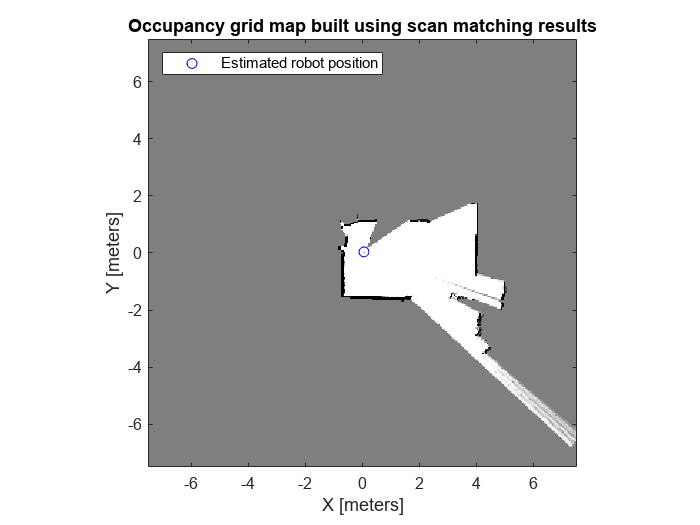

figure
show(map);
title('Occupancy grid map built using scan matching results');
hold on
plot(poseList(:,1),poseList(:,2),'bo','DisplayName','Estimated robot position');
legend('show','Location','NorthWest')
hold off